# Comparison Example Part 2: Sampling from the Affine-transformed Isotropic Gaussian Function

## Problem: 

This case study is based on the literature by [Goodman and Weare (2010)](https://projecteuclid.org/download/pdf_1/euclid.camcos/1513731992).

In this second part of the comparison example, the variables of the ansiotropic target distribution function $\pi \left(\mathit{\mathbf{x}}\right)$ undergo an Affine transformation. This form of scaling is done so as to simplify the form of the target distribution and make it easier to sample from. This is one strategy to adopt should one encounter a poorly-scaled target distribution such as $\pi \left(\mathit{\mathbf{x}}\right)$. An affine transformation is an invertible $R^{\mathit{dim}} \;\mapsto R^{\mathit{dim}}$ space linear mapping from $\mathit{\mathbf{x}}$ to $\mathit{\mathbf{y}}$ as follows:


$$\mathit{\mathbf{x}}\mapsto \mathit{\mathbf{y}}=\hat{A} \cdot \mathit{\mathbf{x}}+\mathit{\mathbf{b}}$$


whereby $\hat{A}$ is a $\mathit{dim}\times \mathit{dim}$ non-singular scaling matrix, while $\mathit{\mathbf{b}}$ is a $\mathit{dim}\times 1$ linear scaling vector.

The target distribution demonstrates affine invariance if the following condition is held:


$$\pi \left(\mathit{\mathbf{x}}\right)\mapsto \pi_{\mathit{\mathbf{T}}} \left(\mathit{\mathbf{y}}\right)=\pi_{\mathit{\mathbf{T}}} \left(\hat{\mathit{\mathbf{A}}} \cdot \mathit{\mathbf{x}}+\mathit{\mathbf{b}}\right)\propto \pi \left(\mathit{\mathbf{x}}\right)$$


Now back to the drawing board. In Part 1, we had a poorly-scaled ansiotropic target distribution taking on the following form:


$$$$$$

$$\pi \left(\mathit{\mathbf{x}}\right)\propto \mathrm{exp}\left\lbrack -\frac{{\left(x_1 -x_2 \right)}^2 }{2\cdot \epsilon }-\frac{{\left(x_1 +x_2 \right)}^2 }{2}\right\rbrack$$


whereby $\epsilon =0\ldotp 01$ is the scaling factor which dictates the degree of anisotropy of $\pi \left(\mathit{\mathbf{x}}\right)$. Using an Affine transformation in the form of:


$$\left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{1}{\sqrt{\epsilon }} & -\frac{1}{\sqrt{\epsilon }}\\
1 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$$


This implies the following transformations:


$$\begin{array}{l}
y_1 =\frac{1}{\sqrt{\epsilon }}\left(x_1 -x_2 \right)\\
y_2 =\left(x_1 +x_2 \right)
\end{array}$$


From there, we get the resulting Affine-transformed target distribution:


$$\pi_T \left(\mathit{\mathbf{y}}\right)\propto \mathrm{exp}\left\lbrack -\frac{{y_1 }^2 }{2}-\frac{{y_2 }^2 }{2}\right\rbrack$$


As you can see now, this scaled target distribution $\pi_T \left(\mathit{\mathbf{y}}\right)$takes the form of an isotropic 2D Gaussian function and is now independent of the scaling parameter $\epsilon$. This now makes the sampling procedure easier. An illustration of the target distribution $\pi_T \left(\mathit{\mathbf{y}}\right)$is provided below:

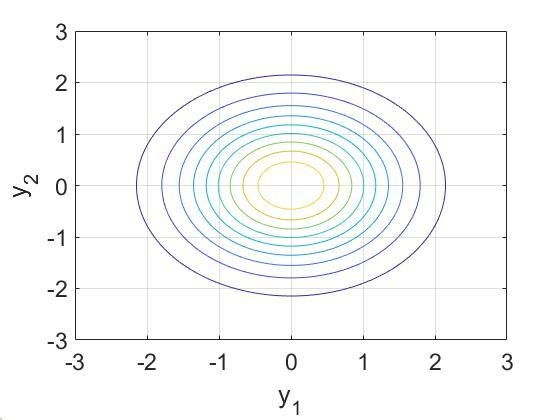

As per in Part 1, we will be using the Ensemble sampler with Affine Invariance (ESAI) and the Metropolis-Hastings (MH) sampler to sample from $\pi_T \left(\mathit{\mathbf{y}}\right)$. For each of the samplers, sampling from this target distribution will be done through initiating 4 sampling chains, each chain generating 2000 samples.

## 1) Setting-up the problem:

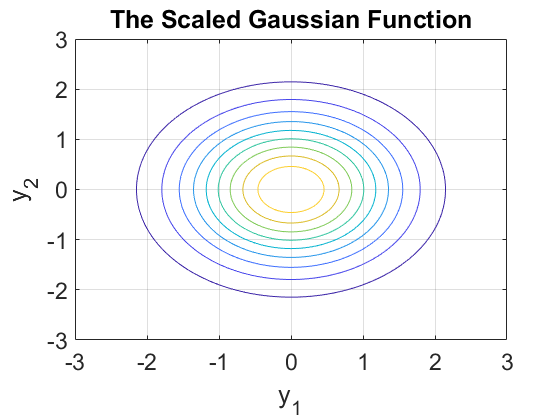

% Number of dimensions of the problem:
dim = 2; 

% Defining the log-target distribution:
logPscaled = @(x) -((x(:,1)).^2 + (x(:,2)).^2)./2;

% To generate an illustrative contour plot of the target distribution:
[Y1,Y2] = meshgrid(-3:.01:3,-3:.01:3);
Z_scaled = logPscaled([Y1(:) Y2(:)]); 
Z_scaled = reshape(Z_scaled,size(Y1));

figure();
hold on; box on; grid on;
contour(Y1,Y2,exp(Z_scaled))
colormap(parula)
grid on
title('The Scaled Gaussian Function')
xlim([-3 3])
ylim([-3 3])
xlabel('y_1')
ylabel('y_2')
set(gca, 'fontsize', 17)

## 2) Sample using the Ensemble sampler:

### a) Defining the input parameters:

% Defining the total number of chains of the ensemble:
Nwalkers = 2*dim;  

% Defining the starting point of each chain:
start_emcmc = unifrnd(-4, 4, Nwalkers, dim);

% Defining the sample size per chain:
Nsamples_emcmc = 2000;

% Defining the burn-in length of each chain:
BurnIn_emcmc = 50;

% Defining the step-size of each chain:
step_size = 7; 
% Note: The step-size is chosen such that it gives the Ensemble sampler an
% overall acceptance rate that is close to 0.235.

### b) Initiate the Ensemble sampler:

tic;
EMCMC2 = EMCMCsampler(start_emcmc,logPscaled,Nsamples_emcmc,'StepSize',step_size,'burnin',BurnIn_emcmc);

timeEMCMC_2 = toc;
fprintf('Time elapsed is for the Ensemble sampler for Anisotropic case: %f \n',timeEMCMC_2)

Time elapsed is for the Ensemble sampler for Anisotropic case: 1.988913 


fprintf('The acceptance level of the Ensemble sampler for Anisotropic case is %d. \n',EMCMC2.acceptance)

The acceptance level of the Ensemble sampler for Anisotropic case is 2.621945e-01. 


### c) To obtain the sample output:

% To extract the samples:
samps2_emcmc = EMCMC2.samples;

% Note that the output is in the form of a Nsamples x dim x Nwalker matrix.
% We need to flatten the chain and convert it to a N x dim matrix:
samples_emcmc_2 = permute(samps2_emcmc, [2 1 3]);
samples_emcmc_2 = samples_emcmc_2(:,:)';

## 3) Sample using the MH sampler:

### a) Defining the input parameters:

% Defining the total number of chains of the MH sampler:
Nchains = Nwalkers;  

% Defining the tuning parameter of the MH sampler:  
tuning_mh = [5, 0; 0, 5];
% Note: The tuning parameter is chosen such that it gives the MH sampler an
% overall acceptance rate that is close to 0.235.

% Defining the proposal function of the MH sampler:
proppdf = @(CandidateSample,CurrentSample) mvnpdf(CandidateSample,CurrentSample,tuning_mh);
proprnd = @(CurrentSample) mvnrnd(CurrentSample,tuning_mh);

% Defining the starting point of each chain:
start_mh = unifrnd(-4, 4, Nchains, dim);

% Defining the sample size per chain:
Nsamples_mh = 2000;

% Defining the burn-in length of each chain:
BurnIn_mh = 50;

### b) Initiate the Metropolis-Hastings sampler:

tic; 
[samps2_mh,accept_2] = mhsample(start_mh,Nsamples_mh,'logpdf',logPscaled,'proppdf',proppdf...
    ,'proprnd',proprnd,'symmetric',1....
    ,'burnin',BurnIn_mh,'nchain',Nchains);
timeMH_2 = toc;
fprintf('The acceptance level of the MH sampler for Isotropic case is %d. \n',accept_2)

The acceptance level of the MH sampler for Isotropic case is 2.551220e-01. 
The acceptance level of the MH sampler for Isotropic case is 2.375610e-01. 
The acceptance level of the MH sampler for Isotropic case is 2.409756e-01. 
The acceptance level of the MH sampler for Isotropic case is 2.551220e-01. 


fprintf('Time elapsed is for the MH sampler for Isotropic case: %f \n',timeMH_2)

Time elapsed is for the MH sampler for Isotropic case: 0.230414 


### c) To obtain the sample output:

% Note that the output is in the form of a Nsamples x dim x Nchains matrix.
% We need to flatten the chain and convert it to a N x dim matrix:
samples_mh_2 = permute(samps2_mh, [2 1 3]);
samples_mh_2 = samples_mh_2(:,:)';

## 3) Save the data and run the next part:

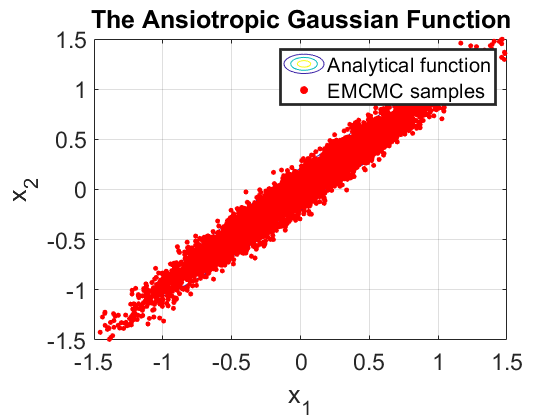

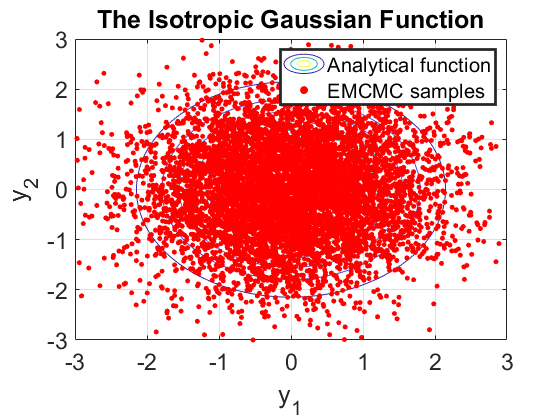

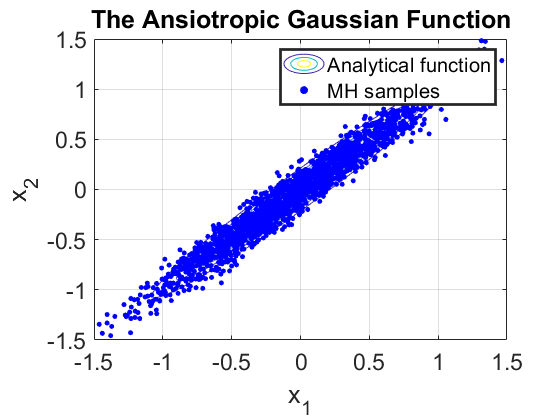

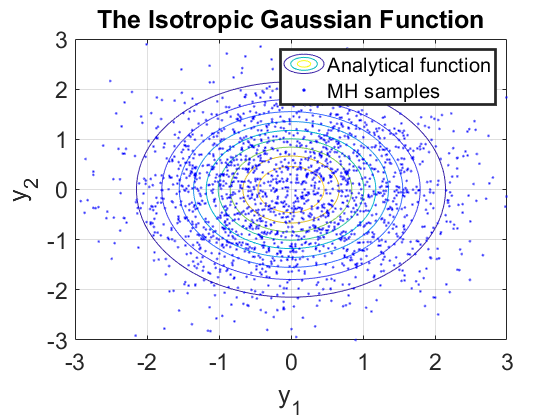

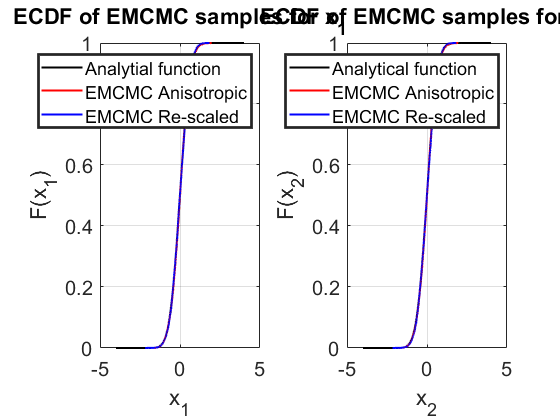

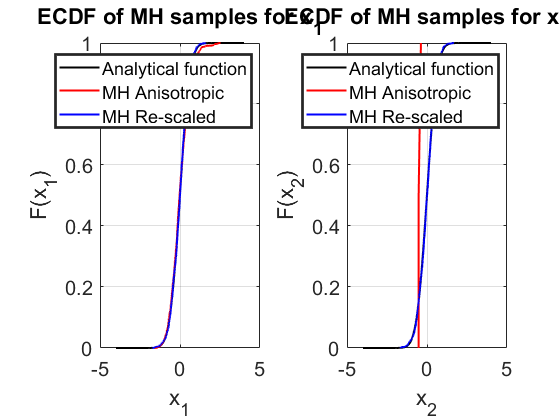

% To save all the data from this file:
save Example_Comparison_Part2.mat;

% To run the next example:
run("Example_Comparison_Part3.mlx");

%%%%%%%%%%%%%%%%%%%%%%%%%%%% End of code %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%